clear
close all
clc

s = tf("s");

## From fdt to state-space

In this section the state-space model is obtained from the transfer function.

%The following transfer function are in RPM so it need to be divided by
%9.54929 for obtaining the conversion in rad/s.

% 1/s is due to the fact we want the output of fdt to be a position.


% Provided model
G = (7.1 / (1 + (s* 0.065)) )* 1/(9.54929*s);

% Model obtained with areas approach
G_new = (6.893 / (1 + (s* 0.094)) )* 1/(9.54929*s);

%Obtain state-space model from transfer function
sys = ss(G_new);
A = sys.A;
B = sys.B;
C = sys.C;
D = sys.D;

## Reachability

After it has been obtained state-space representation, it must be checked system's reachability by verifying that the rank of the reachability matrix is equal to the system degree.

% Reachability matrix of the original system
Wr=[B A*B]

Wr =     2.0000  -21.2766
         0    2.0000


Wr_rank=rank(Wr)

Wr_rank = 2

## State transformation

It needs to transform the C matrix for ensuring that it's equal to [0 1]. This is for avoiding to divide the output by a multiplying factor in Simulink.

% Transformation matrix T to change C to [0 1] 

% Define transformation matrix in a symbolic way
syms a b c d
T = [a,b; c,d];

% Inverse of T
T_inv = inv(T);



% Symbolic matrix of the transformed system
A_t = T_inv*A*T;
B_t = T_inv * B;
C_t = C * T;

% Equations to solve in order to obtain T such that the transformed A
% matrix is equal to the original A and C transformed is equal to the row
% vector [0 1]
eq1 = A_t == A;
eq2 = C_t == [0, 1];

% Solve the equations
solution = solve([eq1(:); eq2(:)], [a, b, c, d]);

% Extract the solution
a_sol = double(solution.a);
b_sol = double(solution.b);
c_sol = double(solution.c);
d_sol = double(solution.d);

% Construct the transformation matrix T
T_sol = [double(a_sol), double(b_sol); double(c_sol), double(d_sol)];

% Apply the transformation to B and C
T_inv = inv(T_sol)

T_inv =     3.8395         0
         0    3.8395


## Transformed state-space matrix

A_t= T_inv*A*T_sol

A_t =   -10.6383         0
    1.0000         0


B_t= T_inv * B

B_t =     7.6791
         0


C_t= C * T_sol

C_t =      0     1


## Reachability of the transformed system

% Reachability matrix of the transformed system
Wrt=[B_t A_t*B_t]

Wrt =     7.6791  -81.6924
         0    7.6791


% Check the rank of Wrt is equal both to the rank of Wr and system's order 
Wrt_rank = rank(Wrt)

Wrt_rank = 2


% Display the results
disp('Transformation matrix T:');

Transformation matrix T:


disp(T_sol);

    0.2604         0
         0    0.2604



disp('Transformed B matrix:');

Transformed B matrix:


disp(B_t);

    7.6791
         0



disp('Transformed C matrix:');

Transformed C matrix:


disp(C_t);

     0     1



## Transformed state-space system

Create new state-space system with transformed matrix

sys_t= ss(A_t, B_t, C_t, D)

sys_t =
 
  A = 
           x1      x2
   x1  -10.64       0
   x2       1       0
 
  B = 
          u1
   x1  7.679
   x2      0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Prope

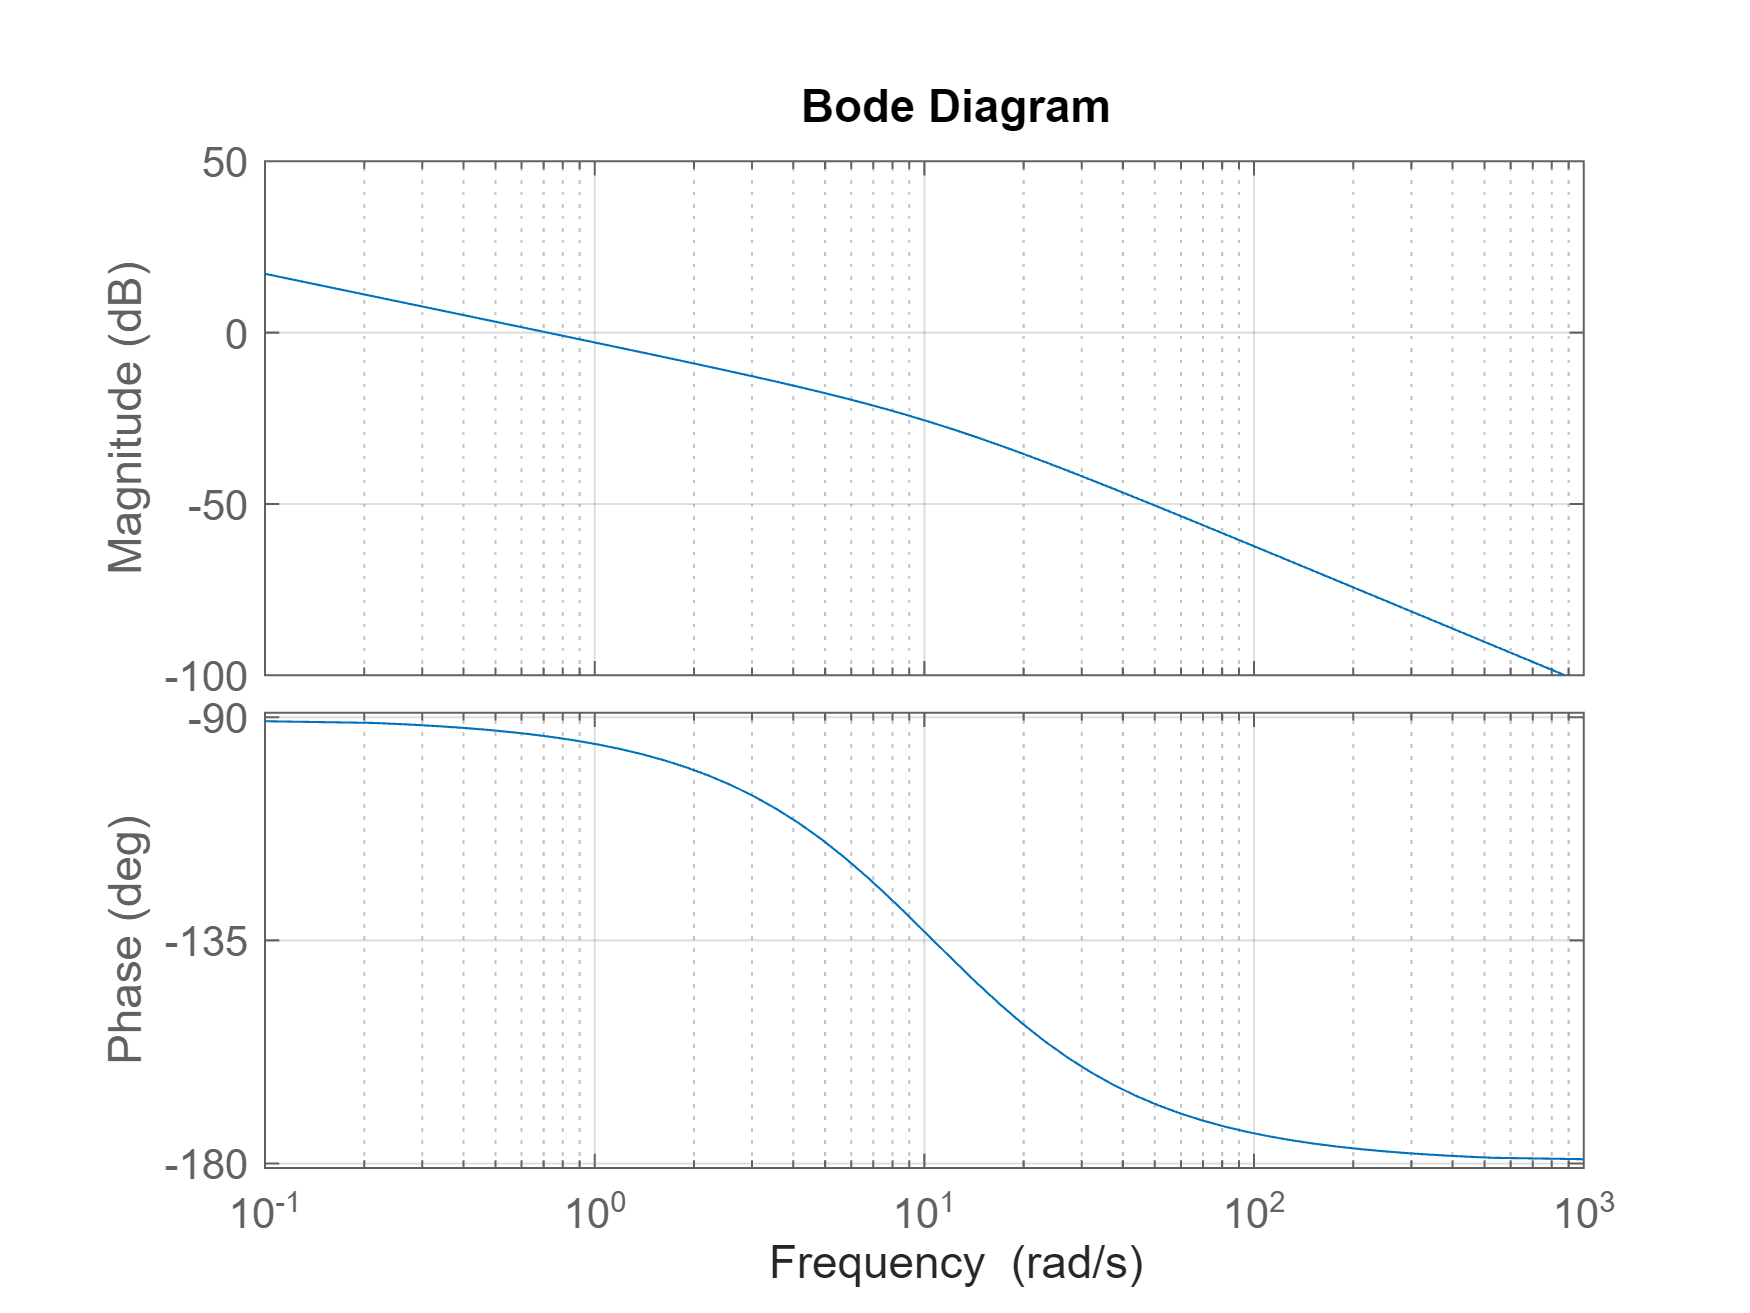

% Bode Open Loop
figure
bode(tf(sys_t))
grid on;

## Comparison between original system's step response and transformed system's step response

This comparison is for checking state transformation correctness. The two step response have to be equal.

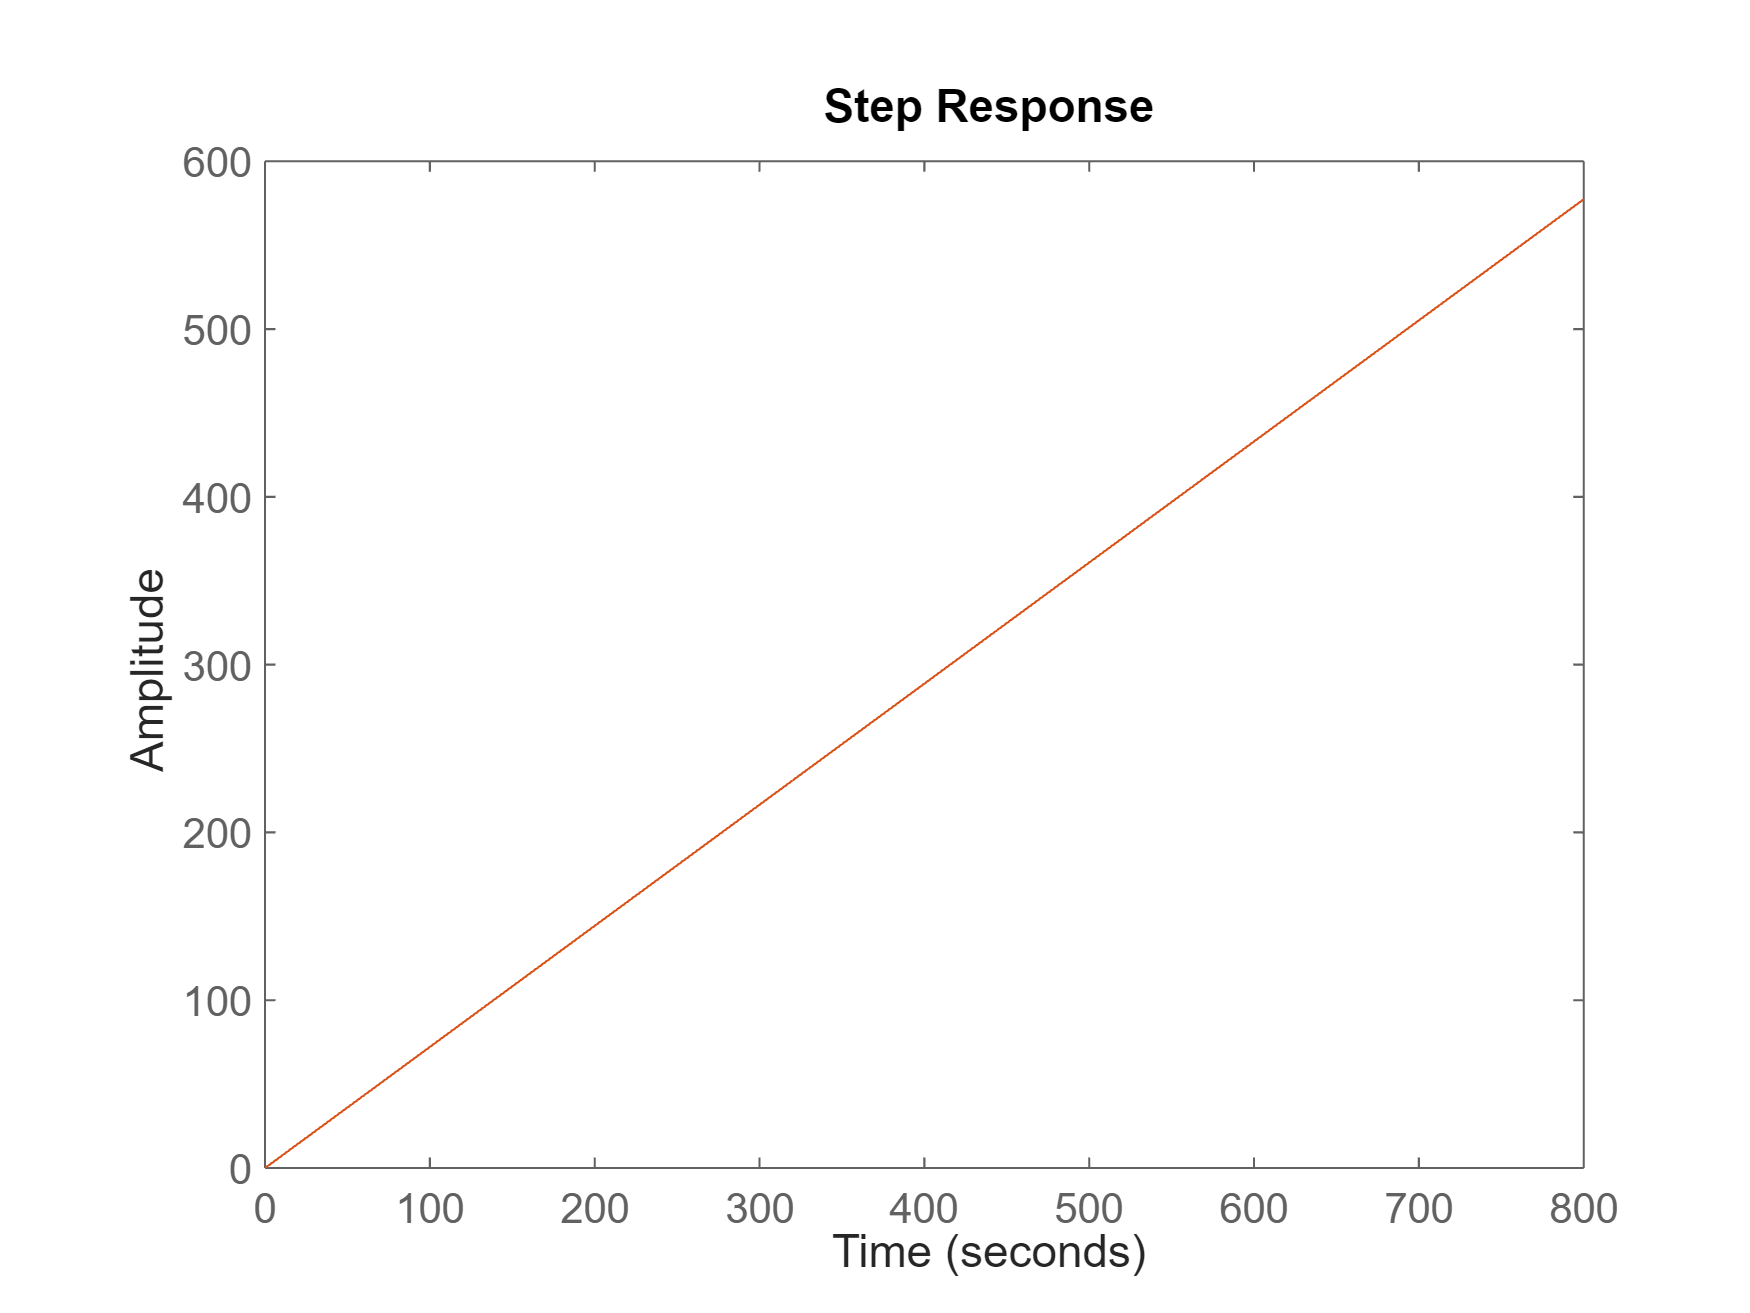

figure
hold on
step(sys)
step(sys_t)
hold off

## LQI Design

In this phase, the LQI control is designed and tuned. The weights of Qz and Qv has been chosen and then the optimization problem is resolved in order to obtain the optimal gain K.

% LQI design with the transformed system
Qz = [0.015 0 0; 0 1 0; 0 0 35];

Qv = 1e-03;

% Obtaining gain for state-feedback control
[K,S,e] = lqi(sys_t,Qz,Qv); 

K_12 =[K(1), K(2)];

Kr = -1/(C_t*inv(A_t-B_t*K_12)*B_t);

Ki = -K(3);

% Integrator
Ki_s = -K(3)/s;



disp('LQI gain matrix K:');

LQI gain matrix K:


disp(K);

    4.2194   55.6518 -187.0829



disp('Reduced gain matrix K_12:');

Reduced gain matrix K_12:


disp(K_12);

    4.2194   55.6518



disp('Reference gain Kr:');

Reference gain Kr:


disp(Kr);

   55.6518



disp('Integral gain Ki:');

Integral gain Ki:


disp(Ki_s);

  tf with properties:

       Numerator: {[0 187.0829]}
     Denominator: {[1 0]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## State-space representation in Discrete Time domain

The sampling period has been defined. Subsequently the time-continous model and the integrator term of the control law are discretized.

The model can be simulated in continous domain but for checking the performance of the control systems on real hardware, the control law has to be discrete.

%Sampling time
Ts=0.005;

% System discretization
sys_td = c2d(sys_t,Ts, 'tustin');

% Discretization  of the integrator
Ki_d = c2d(Ki_s,Ts,'tustin');

disp('Transformed State-Space System in Discrete-Time:');

Transformed State-Space System in Discrete-Time:


disp(sys_td);

  ss with properties:

                A: [2×2 double]
                B: [2×1 double]
                C: [0.0024 1]
                D: 4.6751e-05
                E: []
           Scaled: 0
        StateName: {2×1 cell}
        StatePath: {2×1 cell}
        StateUnit: {2×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: 0
      OutputDelay: 0
        InputName: {''}
        InputUnit: {''}
       InputGroup: [1×1 struct]
       OutputName: {''}
       OutputUnit: {''}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0.0050
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]




disp('Integral gain in Discrete Time Ki_d:');

Integral gain in Discrete Time Ki_d:


disp(Ki_d);

  tf with properties:

       Numerator: {[0.4677 0.4677]}
     Denominator: {[1 -1]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0.0050
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## Extended system with integral action

For developing a control law with integral action it needs to add a state variable $\dot{\;z} =y-r$. These state ensures that at steady-state the system's output follow the reference. The model is extended as follow:


[n, m] = size(B_t);
[p, ~] = size(C_t);


% It is -C_t because from Matlab doc we know that lqi command computes the
% optimal gain matrix K by considering the error as r-y, while the equation
% for extending the system is y-r.

A_ext = [A_t, zeros(n, 1); -C_t, 0]; 
B_ext = [B_t; zeros(p, 1)];
C_ext = [C_t, 0];
D_ext = 0;

% State space representation of the extended system
sys_ext = ss(A_ext, B_ext, C_ext, D_ext);


## Closed loop system

In this section it has been defined state-space model of the closed loop system. The matrices of the system are calculated as follow:

% State space representation of the closed loop system
A_cc = [A_t-B_t*K_12, -B_t*Ki; C_t, 0]

A_cc = 1.0e+03 *

   -0.0430   -0.4274   -1.4366
    0.0010         0         0
         0    0.0010         0


B_cc = [0; 0; 1]

B_cc =      0
     0
     1


C_cc = [C_t, 0]

C_cc =      0     1     0


D_cc = 0;

sys_cc = tf(ss(A_cc,B_cc,C_cc,D_cc))

sys_cc =
 
               -1437
  --------------------------------
  s^3 + 43.04 s^2 + 427.4 s + 1437
 
Continuous-time transfer function.
Model Properties


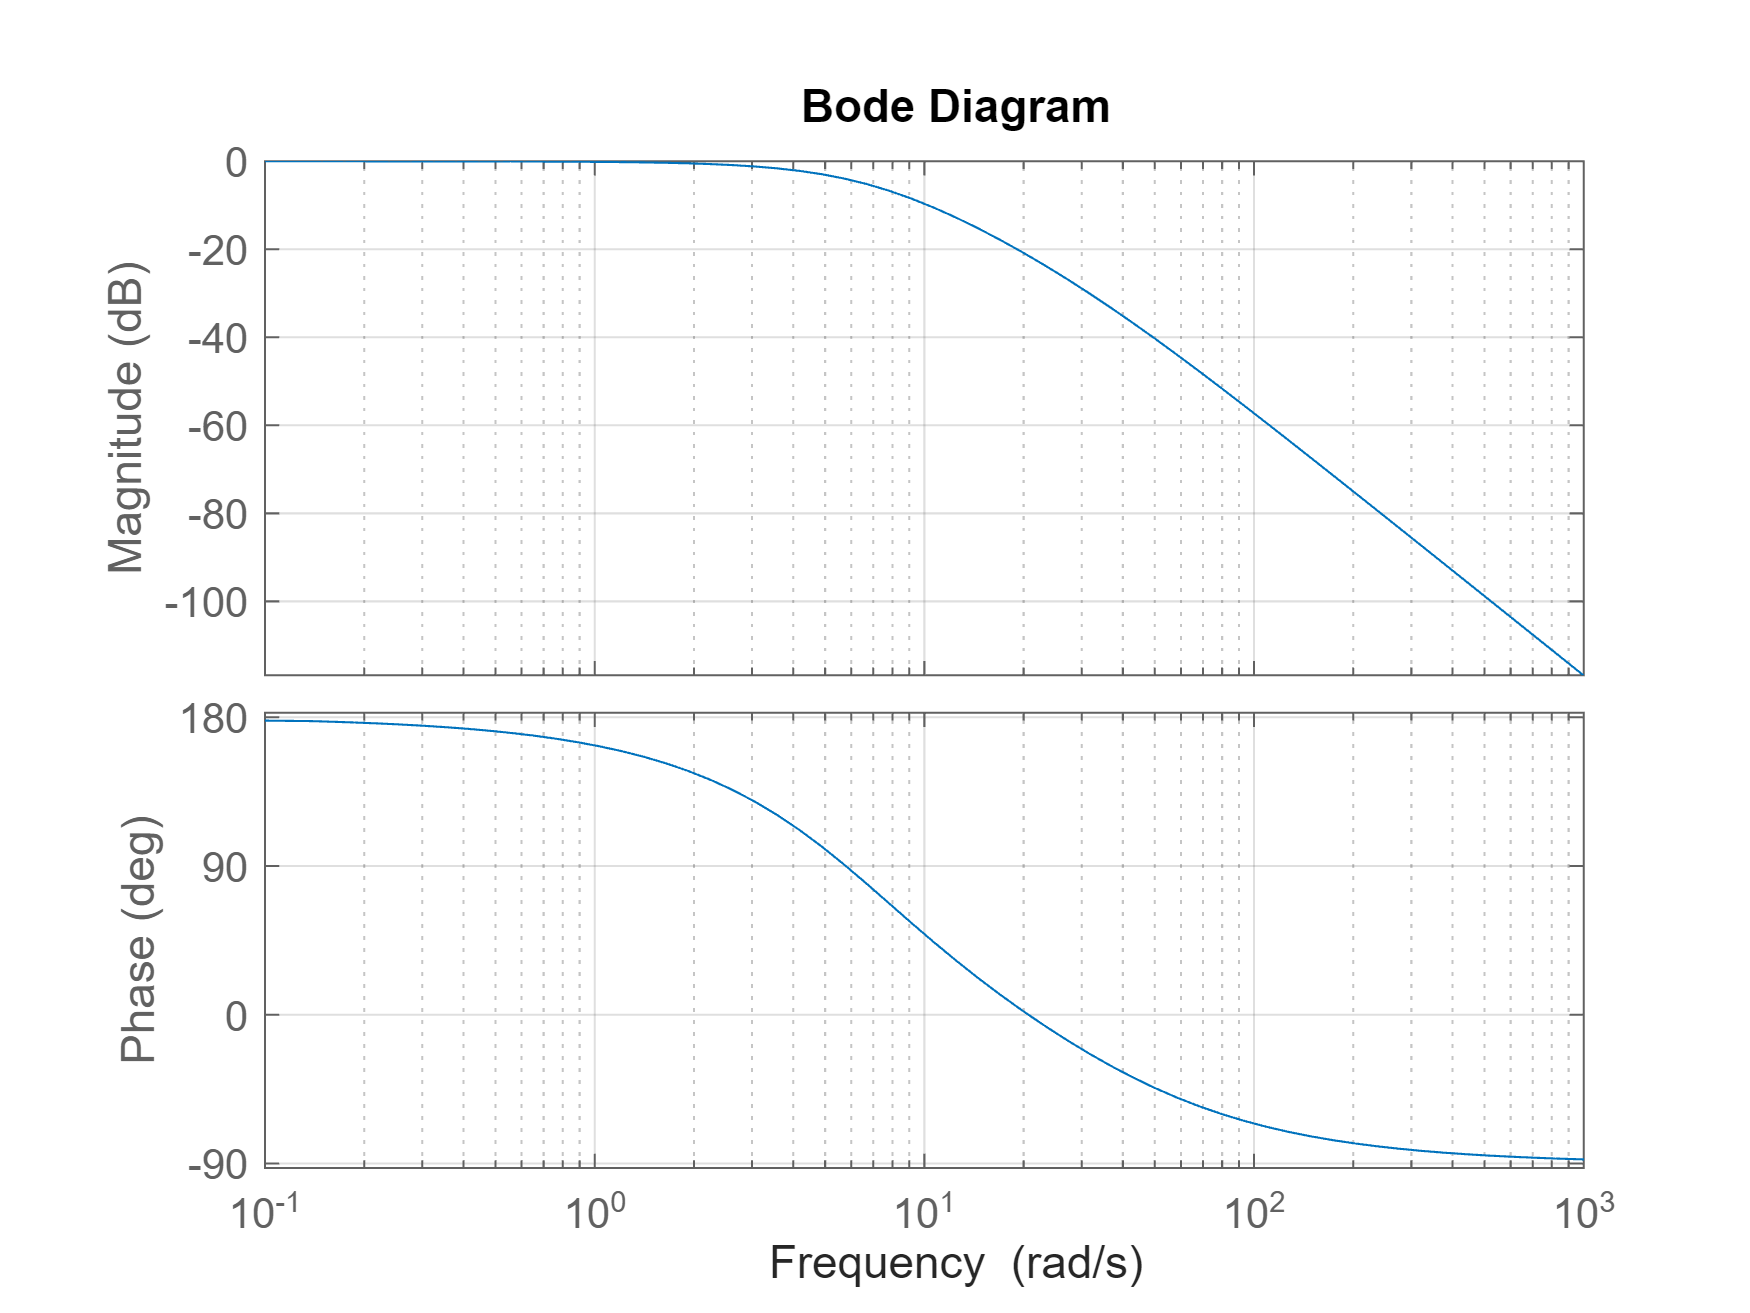

figure

% Bode Closed Loop
bode(sys_cc)
grid on

### Closed loop Bandwidth

cc_bandwidth = bandwidth(sys_cc)

cc_bandwidth = 4.9459

## Simulation results of the designed LQI

In this section the model is simulated and the results are showed. In addition to dynamic and steady-state performance, it is possible to observe disturbance rejection.

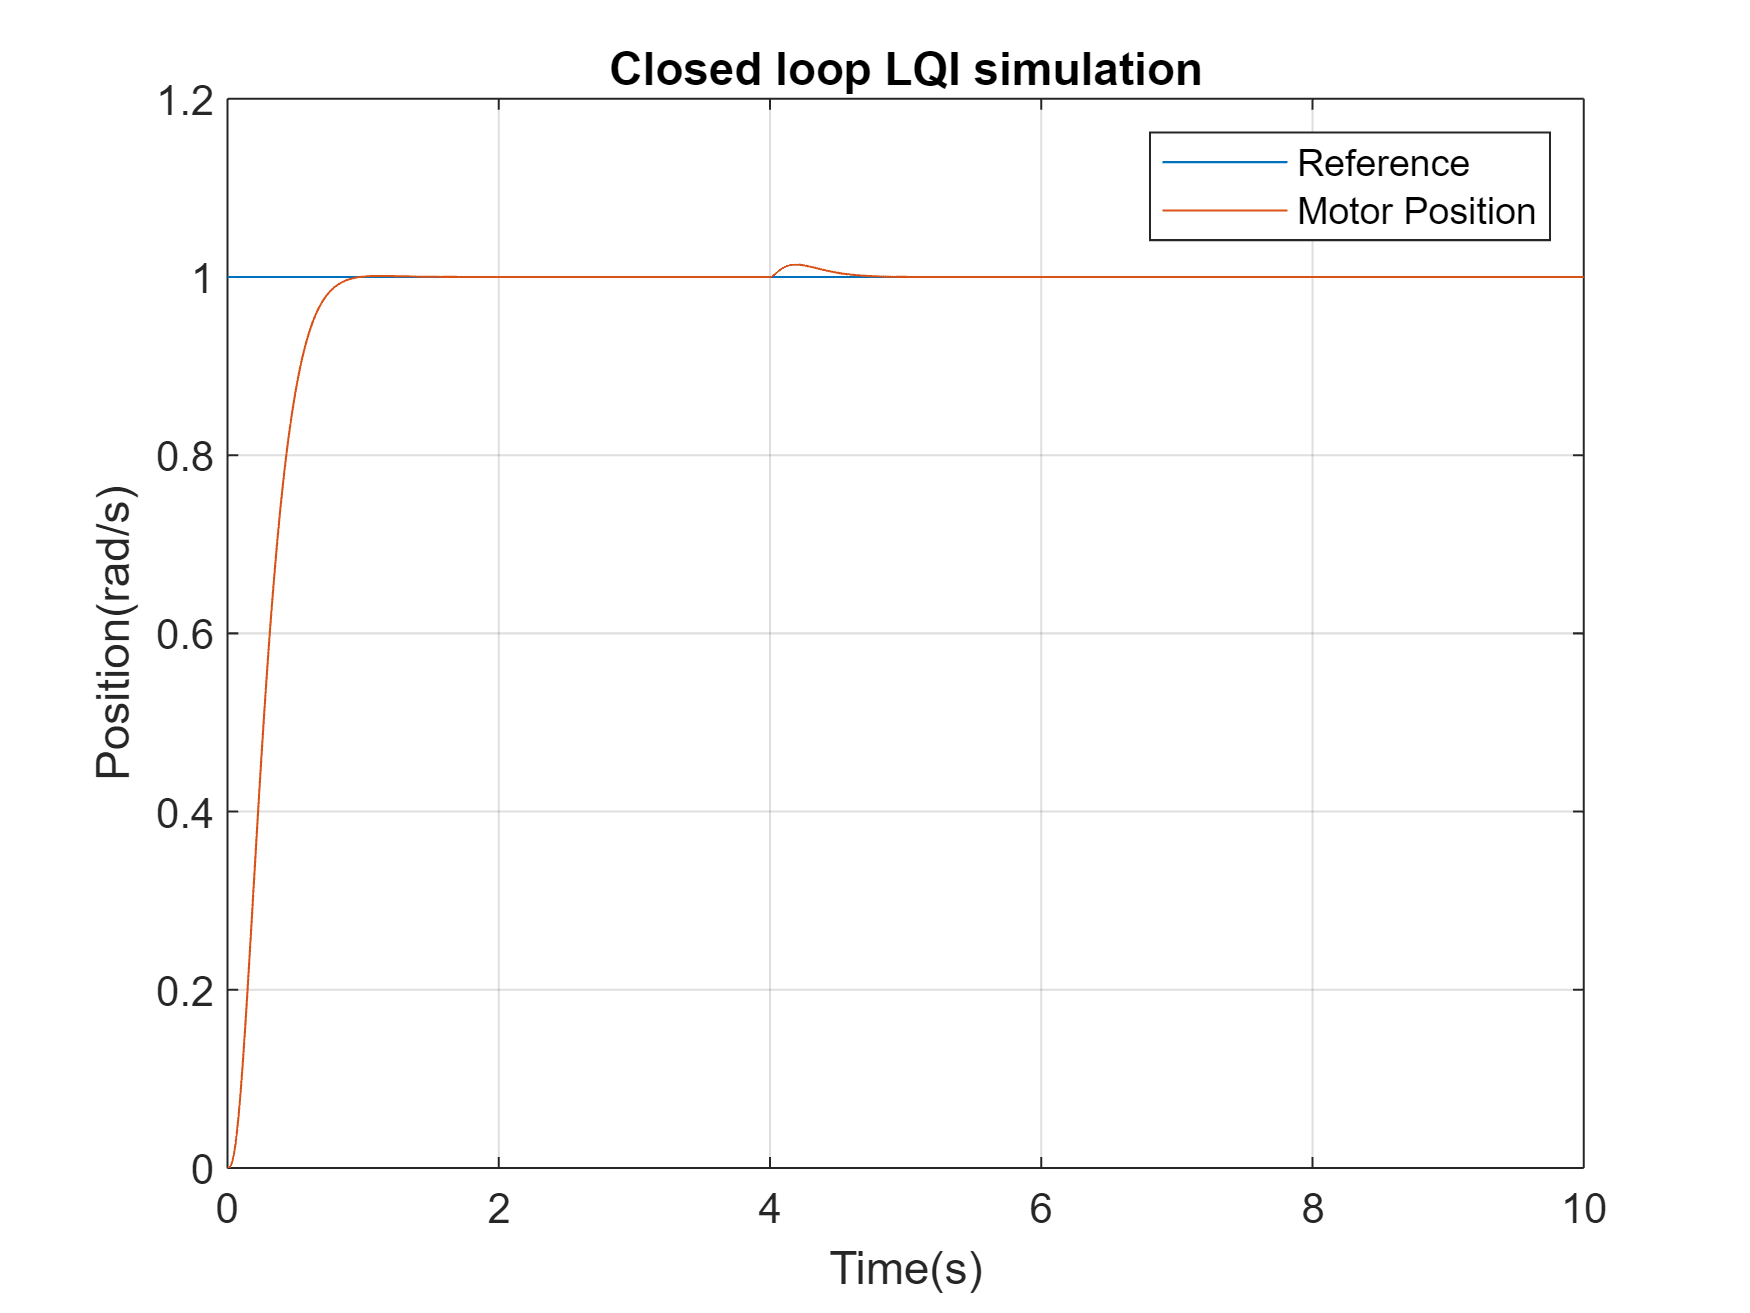

simulation = sim('position_control_simulation_sm');
figure
plot(simulation.ref)
hold on
plot(simulation.position)

xlabel('Time(s)');
ylabel('Position(rad/s)');
title('Closed loop LQI simulation');

LQI_sim_Strings{1} = ['Reference'];
LQI_sim_Strings{2} = ['Motor Position'];

legend(LQI_sim_Strings);

grid on;